# ESERCITAZIONE___11/03/2026___SALVATORE_RAIOLA_DE6000008

clear; close all; clc;

## 0)  DEFINIZIONI 

#### Variabili Simboliche 

syms q1 q2 dq1 dq2 ddq1 ddq2 u1 u2 w real

#### Parametri

m1 = 1.0;
m2 = 1.2;
k1 = 20;
k2 = 25;
c1 = 1;
c2 = 1.2;
k = 15;
c = 0.8;
k3 = 40;

#### I-S-U

% Ingresso
u = [u1;
     u2];

% Stato
x = [q1;
     q2;
     dq1;
     dq2];

% Uscita
y = [q1;
     q2];

#### Modello Dinamico

% Equazioni del sistema
eq_1_sym = -k1*q1 - c1*dq1 + k*(q2-q1) + k3*(q2-q1)^3 + c*(dq2-dq1) + u1 == m1*ddq1;
eq_2_sym = -k2*q2 - c2*dq2 - k*(q2-q1) - k3*(q2-q1)^3 - c*(dq2-dq1) + u2 == m2*ddq2;

eqs_sym = [eq_1_sym;
           eq_2_sym];

% Risolviamo il sistema di equazioni nelle variabili ddq1 e ddq2
sol = solve(eqs_sym, [ddq1, ddq2], "ReturnConditions",true);

% dx/dt
f = [dq1;
     dq2;
     sol.ddq1;
     sol.ddq2]

$$f = \left(\begin{array}{c} {\mathrm{dq}}_{1}\\ {\mathrm{dq}}_{2}\\ \frac{4\,{\mathrm{dq}}_{2}}{5}-\frac{9\,{\mathrm{dq}}_{1}}{5}-35\,q_{1}+15\,q_{2}+u_{1}-40\,{\left(q_{1}-q_{2}\right)}^{3}\\ \frac{2\,{\mathrm{dq}}_{1}}{3}-\frac{5\,{\mathrm{dq}}_{2}}{3}+\frac{25\,q_{1}}{2}-\frac{100\,q_{2}}{3}+\frac{5\,u_{2}}{6}+\frac{100\,{\left(q_{1}-q_{2}\right)}^{3}}{3} \end{array}\right)$$

% y
g = y

$$g = \left(\begin{array}{c} q_{1}\\ q_{2} \end{array}\right)$$

## 1)  PUNTI DI EQUILIBRIO E LINEARIZZAZIONE

#### Punti di equilibrio del sistema

eql = subs(eqs_sym, [ddq1, ddq2, dq1, dq2, u1, u2], [0, 0, 0, 0, 0, 0]);

peql = solve(eql, [q1, q2], "ReturnConditions", true);

q1_bar = double(peql.q1);
q2_bar = double(peql.q2);
dq1_bar = 0.0;
dq2_bar = 0.0;

x_bar = [q1_bar;
         q2_bar;
         dq1_bar;
         dq2_bar];

disp('Punto di equilibrio del sistema : '); x_bar

Punto di equilibrio del sistema : 


x_bar =      0
     0
     0
     0


#### Punto di equilibrio x* corrispondente a u1* = 1 N e u2* = -0.5 N

% Punto di lavoro
u1_star = 1;
u2_star = -0.5;
u_star = [u1_star;
          u2_star];

eql = subs(eqs_sym, [ddq1, ddq2, dq1, dq2, u1, u2], [0, 0, 0, 0, u1_star, u2_star]);

peql_star = solve(eql, [q1, q2], "ReturnConditions", true);

q1_star = double(peql_star.q1);
q2_star = double(peql_star.q2);
dq1_star = 0.0;
dq2_star = 0.0;

x_star = [q1_star;
          q2_star;
          dq1_star;
          dq2_star];

disp('Punto di equilibrio x* corrispondente a u1* = 1 N e u2* = -0.5 N : '); x_star

Punto di equilibrio x* corrispondente a u1* = 1 N e u2* = -0.5 N : 


x_star =     0.0276
   -0.0021
         0
         0


#### Modello Linearizzato nell'intorno di x*

% Matrici Simboliche
A_sym = jacobian(f,x);
B_sym = jacobian(f,u);
C_sym = jacobian(g,x);
D_sym = jacobian(g,u);

A = double(subs(A_sym, [x; u], [x_star; u_star]));
B = double(subs(B_sym, [x; u], [x_star; u_star]));
C = double(subs(C_sym, [x; u], [x_star; u_star]));
D = double(subs(D_sym, [x; u], [x_star; u_star]));

% Numero stati
n = size(A,1);

% Numero Ingressi
m = size(B,2);

% Numero uscite
v = size(C,1);

% Sistema linearizzato in x*, u*
sys = ss(A, B, C, D)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -35.11   15.11    -1.8     0.8
   x4   12.59  -33.42  0.6667  -1.667
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       1       0
   x4       0  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


#### Verifica Stabilità, Controllabilità e Osservabilità

Stabilità

autovalori = eig(A);
parte_reale = real(autovalori);

if all(parte_reale < 0)
    disp('Il sistema è LOCALMENTE ASINTOTICAMENTE STABILE in x*'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
    
elseif any(parte_reale > 0)
    disp('Il sistema è INSTABILE in x*'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
    
else
    % Caso con max(parte_reale) == 0
    disp('Caso critico (autovalori con parte reale nulla). L''analisi lineare con l''approccio agli autovalori è INCONCLUDENTE in x*.'); disp('Autovalori della matrice Jacobiana A in x*:'); disp(autovalori);
end

Il sistema è LOCALMENTE ASINTOTICAMENTE STABILE in x*
Autovalori della matrice Jacobiana A in x*:
  -1.2332 + 6.8234i
  -1.2332 - 6.8234i
  -0.5002 + 4.4943i
  -0.5002 - 4.4943i



Controllabilità

if rank(ctrb(A,B)) == n
    disp('IL sistema è completamente Controllabile');
else
    disp('IL sistema NON è completamente Controllabile');
end

IL sistema è completamente Controllabile


Osservabilità

if rank(obsv(A,C)) == n
    disp('IL sistema è completamente Osservabile');
else
    disp('IL sistema NON è completamente Osservabile');
end

IL sistema è completamente Osservabile


## 2)  ASSEGNAMENTO AUTOVALORI

#### Specifiche

% Condizione iniziale
q1_0 = 0.1;
q2_0 = 0.3;
x_0 = [q1_0;
       q2_0;
       0.0;
       0.0];

% Riferimento
q1_ref_eig = 0.5;
q2_ref_eig = 1;
x_ref = [q1_ref_eig;
         q2_ref_eig];

% Autovalori desiderati (N.B. viene applicato un piccolo shift per utilizzare il comando place)
delta_eig = 0.0001;
eig_des = [-5, -5-delta_eig, -10, -10-delta_eig];

#### Sintesi

K_eig = place(A, B, eig_des)

K_eig =    64.8948   15.1062   18.2001    0.8000
   15.1062  -10.1056    0.8000   10.0001


A_cl_eig = A-B*K_eig;
eig(A_cl_eig)

ans =   -10.0000
  -10.0001
   -5.0000
   -5.0001


#### Compensazione del guadagno

% Sistema a ciclo chiuso con retroazione di stato
cl_sys_eig = ss(A_cl_eig, B, C, D);

% Guadagno a ciclo chiuso
cl_gain_eig = dcgain(cl_sys_eig);

N = pinv(cl_gain_eig)

N =   100.0010         0
         0   30.0006


#### Verifica Simulazione

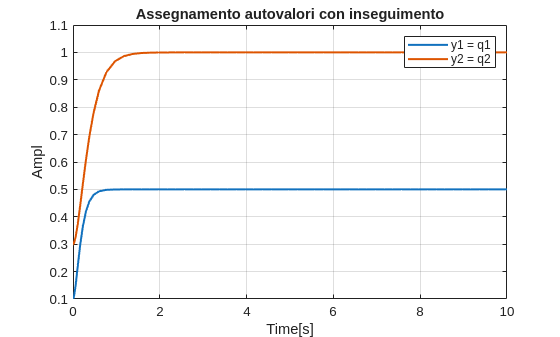

% Plot MATLAB
out = sim('AssegnamentoAutovalori.slx');
y1_eig = out.y1.Data;
y2_eig = out.y2.Data;
time = out.y1.Time;

figure
plot(time, y1_eig, "LineWidth", 1.5);
grid on
hold on 
plot(time, y2_eig, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = q1', 'y2 = q2');
title('Assegnamento autovalori con inseguimento');

## 3)  CONTROLLO LQR CON AZIONE INTEGRALE

#### Specifiche

% Riferimento
q1_ref_lqr = 0.5;

% Tempo di Assestamento
Ts = 0.3;
alpha = 4/Ts;

#### Sistema Aumentato

C_LQR = [1, zeros(1, n-1)];
A_aug = [A, zeros(n,1);
         -C_LQR, 0];  eig(A_aug)

ans =    0.0000 + 0.0000i
  -1.2332 + 6.8234i
  -1.2332 - 6.8234i
  -0.5002 + 4.4943i
  -0.5002 - 4.4943i


n_aug = size(A_aug,1);

% Trasliamo lo spettro di A_aug cosi da rispettare la specifica sul Ts
A_hat = A_aug + alpha*eye(n_aug); eig(A_hat);
B_aug = [B;
         zeros(1,m)];

C_aug = [eye(n) zeros(n,1)];

D_aug = 0;

sys_aug = ss(A_hat, B_aug, C_aug, D_aug)


sys_aug =
 
  A = 
           x1      x2      x3      x4      x5
   x1   13.33       0       1       0       0
   x2       0   13.33       0       1       0
   x3  -35.11   15.11   11.53     0.8       0
   x4   12.59  -33.42  0.6667   11.67       0
   x5      -1       0       0       0   13.33
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3       1       0
   x4       0  0.8333
   x5       0       0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   1   0   0   0
   y3   0   0   1   0   0
   y4   0   0   0   1   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


#### Sintesi

Q_bar = 1;
Q = C_aug'*Q_bar*C_aug + blkdiag(zeros(n,n), 100)

Q =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0   100


R = eye(m)

R =      1     0
     0     1


[K_LQR, ~, ~] = lqr(sys_aug, Q, R);
K_LQR_x = K_LQR(:, 1:n);
K_LQR_i = K_LQR(:, n+1:end);

#### Verifica Simulazione

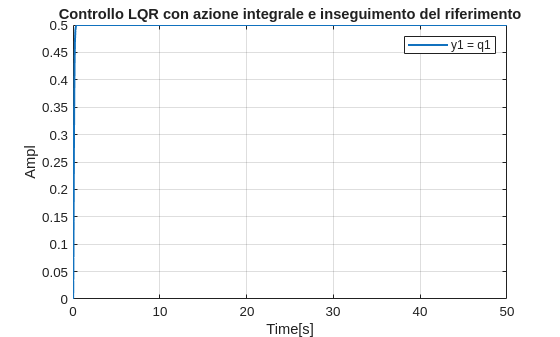

% Plot MATLAB
out = sim('LQR.slx');
y1_lqr = out.y1.Data;
time = out.y1.Time;

figure
plot(time, y1_lqr, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = q1');
title('Controllo LQR con azione integrale e inseguimento del riferimento');

## 4)  CONTROLLO H-INF

#### Modello dinamico con disturbo

% Prima equazione del modello dinamico modificata con il disturbo
eq_1_sym = -k1*q1 - c1*dq1 + k*(q2-q1) + k3*(q2-q1)^3 + c*(dq2-dq1) + u1 + w == m1*ddq1;

eqs_w_sym = [eq_1_sym;
             eq_2_sym];

% Risolviamo il sistema di equazioni nelle variabili ddq1 e ddq2
sol = solve(eqs_w_sym, [ddq1, ddq2], "ReturnConditions",true);

% dx/dt
f = [dq1;
     dq2;
     sol.ddq1;
     sol.ddq2];

% Matrici Simboliche
A_hinf_sym = jacobian(f,x);
Bu_hinf_sym = jacobian(f,u);
Bw_hinf_sym = jacobian(f,w);
C_hinf_sym = jacobian(g,x);
Du_hinf_sym = jacobian(g,u);
Dw_hinf_sym = jacobian(g,w);

A_hinf = double(subs(A_hinf_sym, [x; u; w], [x_star; u_star; 0]));
Bu_hinf = double(subs(Bu_hinf_sym, [x; u; w], [x_star; u_star; 0]));
Bw_hinf = double(subs(Bw_hinf_sym, [x; u; w], [x_star; u_star; 0]));
C_hinf = double(subs(C_hinf_sym, [x; u; w], [x_star; u_star; 0]));
Du_hinf = double(subs(Du_hinf_sym, [x; u; w], [x_star; u_star; 0]));
Dw_hinf = double(subs(Dw_hinf_sym, [x; u; w], [x_star; u_star; 0]));

sys_hinf = ss(A_hinf, [Bw_hinf, Bu_hinf], C_hinf, [Dw_hinf, Du_hinf])


sys_hinf =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -35.11   15.11    -1.8     0.8
   x4   12.59  -33.42  0.6667  -1.667
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3       1       1       0
   x4       0       0  0.8333
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.


n_x = size(A_hinf, 1); % Numero di stati (4)
n_w = 1;               % Un solo disturbo w
n_u = length(u_star);  % Numero di controlli u (2)
n_y = size(C_hinf, 1); % Numero di uscite misurate y (2: q1, q2)

#### Pesi Statici

sigma = 500;
Wq = sigma*eye(m);

rho = 0.8;
Wu = rho*eye(v);


% 2. Vettore di Costo z = [Wq * y; Wu * u]
% Costruiamo la matrice Cz (Legame stato -> costo z)
% Wq pesa le misure y. Siccome y = C_hinf * x, allora z_q = Wq * C_hinf * x.
% Wu pesa u, che è indipendente dallo stato, quindi ci vanno zeri.
Cz = [Wq * C_hinf; 
      zeros(n_u, n_x)];

% Costruiamo la matrice Dzu (Legame controllo u -> costo z)
Dzu = [zeros(n_y, n_u); 
       Wu];

% Costruiamo la matrice Dzw (Legame disturbo w -> costo z)
Dzw = zeros(n_y + n_u, n_w);

Dz = [Dzw, Dzu];

% 3. Assemblaggio Finale di P
B_P = [Bw_hinf, Bu_hinf]; % Ingressi: prima w, poi u
C_P = [Cz; 
       C_hinf];           % Uscite: prima z, poi y
D_P = [Dz; 
       Dw_hinf, Du_hinf];

% Creazione del Plant in Spazio di Stato
P = ss(A_hinf, B_P, C_P, D_P);

#### Sintesi

% hinfsyn ha bisogno di sapere quante misurazioni legge e quanti controlli genera
nmeas = n_y; % 2
ncont = n_u; % 2

[K_hinf, CL, gamma] = hinfsyn(P, nmeas, ncont);

% Stampa del risultato
if gamma < 1
    fprintf('\n---> SINTESI RIUSCITA. Gamma = %.4f\n', gamma);
else
    fprintf('\n---> SINTESI SUB-OTTIMA. Gamma = %.4f (Il sistema fa fatica a rispettare i pesi scelti)\n', gamma);
end


---> SINTESI RIUSCITA. Gamma = 0.8076


#### Verifica Simulazione

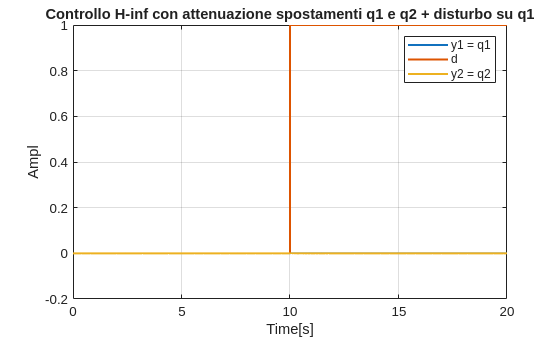

% Plot MATLAB
out = sim('HINF.slx');
y1_hinf = out.y1.Data;
y2_hinf = out.y2.Data;
d_hinf = out.d.Data;
u_hinf = out.u.Data;
time = out.d.Time;

figure
plot(time, y1_hinf, "LineWidth", 1.5);
grid on
hold on
plot(time, d_hinf, "LineWidth", 1.5);
hold on 
plot(time, y2_hinf, "LineWidth", 1.5);
xlabel("Time[s]");
ylabel("Ampl");
legend('y1 = q1', 'd', 'y2 = q2');
title('Controllo H-inf con attenuazione spostamenti q1 e q2 + disturbo su q1');
hold off

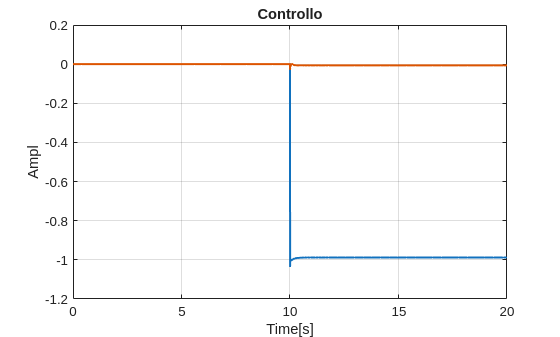

plot(time, u_hinf, "LineWidth", 1.5);
grid on
xlabel("Time[s]");
ylabel("Ampl");
title('Controllo');

## 5)  H-INF CON FUNZIONI DI PESO

Si desidera progettare un controllore robusto K(s) ad anello chiuso che garantisca prestazioni di tracciamento dei riferimenti (Tracking) e reiezione del rumore di misura (Noise Rejection). Abbandonando la reiezione dei disturbi statici sulla dinamica, si formalizza il problema di Mixed Sensitivity specificando i seguenti vincoli per le funzioni di sensitività S(s) e sensitività complementare T(s):

**Inseguimento del Riferimento (Filtro Ws sulla matrice S):**

- Errore massimo a regime permanente per ingressi a gradino unitario: e_ss <= 1% (0.01).

- Tempo di assestamento desiderato: Ts circa 0.5 s.

- Sovraelongazione massima ammessa: PO <= 10%.

**Reiezione del Rumore di Misura (Filtro Wt sulla matrice T):**

- Attenuazione minima di 40 dB per frequenze superiori a wn = 50 rad/s.

**Sforzo di Controllo (Filtro Wu sulla matrice KS):**

- Sforzo di controllo limitato mediante una matrice di penalizzazione statica pari a Wu = 0.05 * I (matrice identità 2x2).

#### Specifiche

ess = 0.1;
Ts_hinf = 5;
PO_perc = 60;

wn = 50;
attenuazione_dB = 10;

rho_2 = 0.5;

#### Funzioni di Peso

s = tf('s');

Ws

As = ess;
wc = 4/Ts_hinf;
PO = PO_perc/100;
zeta = -log(PO) / sqrt(pi^2 + log(PO)^2);
Ms = 1/(2*zeta);

Ws_siso = (s/Ms + wc)/(s+As*wc)


Ws_siso =
 
     s + 2.492
  ----------------
  3.115 s + 0.2492
 
Continuous-time transfer function.


Ws = Ws_siso*eye(v);

Wt

At = 1e-4;
Mt = 10^(attenuazione_dB/20);

Wt_siso = (s + At*wn)/(s/Mt + wn)


Wt_siso =
 
  3.162 s + 0.01581
  -----------------
      s + 158.1
 
Continuous-time transfer function.


Wt = Wt_siso*eye(v);

Wu

Wu = rho_2*eye(m)

Wu =     0.5000         0
         0    0.5000


#### Sintesi

[K, CL, gamma] = mixsyn(sys, Ws, Wt);
K


K =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1       -0.08   8.713e-18   1.653e-18  -1.974e-18   4.521e-19  -5.627e-19   1.583e-19  -2.389e-19
   x2  -2.041e-13       -0.08   4.608e-14  -5.489e-14   1.284e-14  -1.544e-14   4.425e-15  -6.632e-15
   x3        1524       -1798      -345.6         407      -94.06       111.8      -33.28       48.98
   x4       -1805        2149       407.1      -488.3       111.7      -133.3       38.98         -59
   x5  -6.902e-14   8.188e-14   1.558e-14  -1.855e-14   4.363e-15  -5.202e-15           1   -2.24e-15
   x6  -3.348e-13   3.971e-13   7.559e-14  -8.998e-14   2.117e-14  -2.523e-14   7.263e-15           1
   x7       95.23      -112.4      -11.72       25.44      -40.99        22.1       -3.88       3.861
   x8      -94.01       111.9        21.2       -17.2       18.41      -40.37       2.697      -4.739
 
  B = 
               u1          u2
   x1           1  -1.784e-20


fprintf('\n=== RISULTATO SINTESI H-INF ===\n');


=== RISULTATO SINTESI H-INF ===


fprintf('Gamma ottenuto: %.4f\n', gamma);

Gamma ottenuto: 0.9256



if gamma <= 1
    disp('OK: Il controllore soddisfa tutte le specifiche richieste.');
else
    disp('ATTENZIONE: Gamma > 1. Le specifiche sono troppo ambiziose.');
    disp('Il sistema rispetterà le forme dei filtri ma con un "ritardo" proporzionale a gamma.');
end

OK: Il controllore soddisfa tutte le specifiche richieste.
